clear all;


genNum = 500;
neuronNum = 10;
inputNum = 2;
% инициализация начальных весов
% w = 20*rand(neuronNum,inputNum)-10;
% u = 20*rand(neuronNum,1) - 10;
w = zeros(neuronNum,inputNum);
u = zeros(neuronNum,1)

u =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


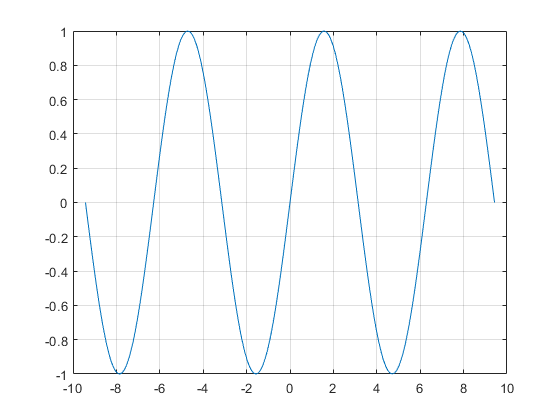

clf;
step = pi/30;
lb = -3*pi;
rb = 3*pi;
XX = [lb:step:rb];
plot(XX, sin(XX))
grid on;

Инициализируем начальные нейроны

% bestResidual = inf
% bestW = zeros(neuronNum,inputNum);
% bestU = zeros(neuronNum);
% tic
% for k = 1:genNum
%     w = 2*rand(neuronNum,inputNum)-1;
%     u = 2*rand(neuronNum,1) - 1;
%     approxFunc = zeros(size(XX));
%     v_residual = zeros(size(XX));
%     for i = 1:numel(XX)
%         buf = zeros([neuronNum,1]);
%         for j = 1:neuronNum
%             buf(j) =  u(j)*neuron(XX(i), w(j,:));
%         end
%         approxFunc(i) = sum(buf);
%         v_residual(i) = (sin(XX(i)) - approxFunc(i))^2;
%     end
%     s_residual = sum(v_residual);
%     if s_residual < bestResidual
%         bestResidual = s_residual;
%         bestW = w;
%         bestU = u;
%     end
% end
% toc
% approxFunc = zeros(size(XX));
% clear residual
% w = bestW;
% u = bestU;
% for i = 1:numel(XX)
%     for j = 1:neuronNum
%         approxFunc(i) = approxFunc(i) + u(j)*neuron(XX(i), w(j,:));
%     end
% end
% hold on;
% plot(XX, approxFunc);

%просто комбинируем параметры чтобы почувствовать; далее эта переменная не
%используется
pars = [reshape(w,[1,neuronNum*inputNum]) u.'];
alpha = 0.3;
fitfunc = @(x)calcResidual(x, XX,neuronNum,inputNum, @neuron, alpha);
tic
bestResidual = inf

bestResidual = Inf

bestPars = zeros(neuronNum*(inputNum+1),1);
for k = 1:genNum
    pars = 20*rand(neuronNum*(inputNum+1),1) - 10;    
    [pars2, s_residual] = fminsearch(fitfunc,pars);

    if s_residual < bestResidual
        bestResidual = s_residual;
        bestPars = pars2;
    end
    
end

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 149.652413 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 260.195285 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 195.861001 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 264.428279 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 209.656310 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 235.919178 

 
Exiting: Maximum number of function evaluations has been exceeded
        


toc

Elapsed time is 4430.078514 seconds.


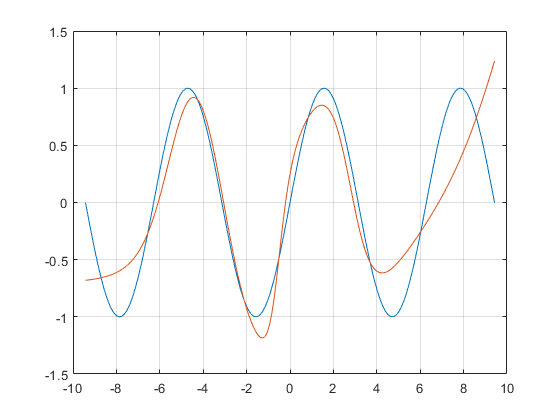

rpars = reshape(bestPars,[neuronNum,inputNum+1]);
w = rpars(:,1:end-1);
u = rpars(:,end);
approxFunc = zeros(size(XX));
for i = 1:numel(XX)
    for j = 1:neuronNum
        approxFunc(i) = approxFunc(i) + u(j)*neuron(XX(i), w(j,:));
    end
end
hold on;
plot(XX, approxFunc);